# **１変数関数の微分可能性**

## **1. 平均変化率**

$x\in\mathbb{R}$ を変数とする1変数関数 $f(x)$ の振る舞いを考えよう. 


$$\frac{f(b)-f(a)}{b-a},
\quad
b \ne a$$


を $f(x)$ の $x=a$ と $x=b$ の間の平均変化率という. これは $y=f(x)$ によって与えられる曲線上の2点 A$\bigl(a,f(a)\bigr)$ と B$\bigl(b,f(b)\bigr)$ を通る直線の傾きである. 

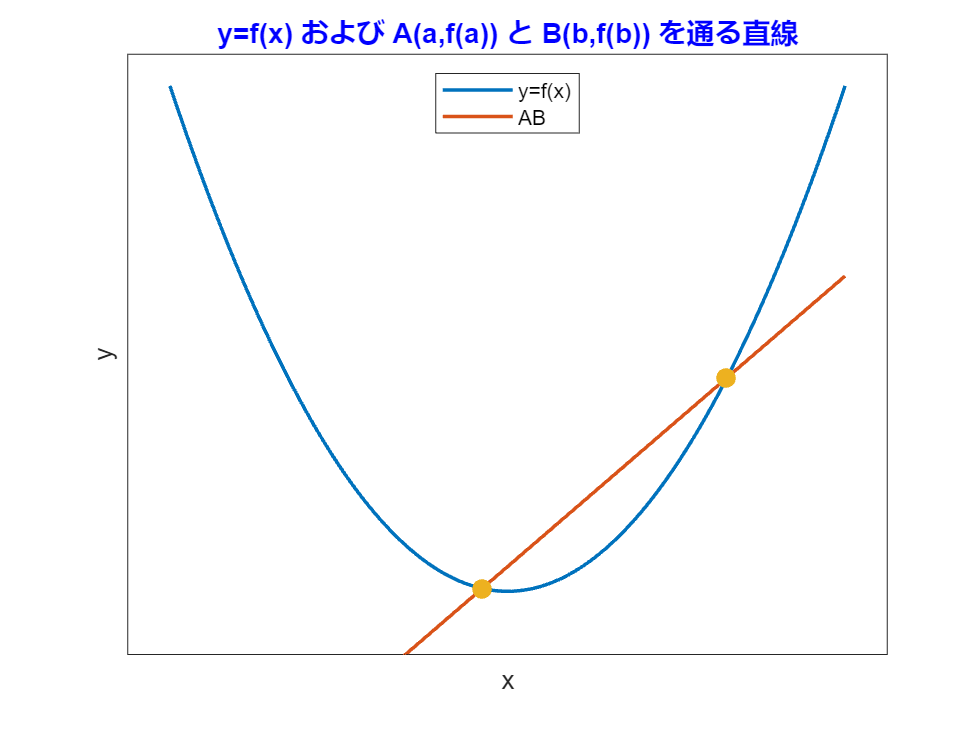

a =-0.3; b =2.6;
p0=zeros(1,2);
q0=zeros(1,2);
p0(1,1)=a;
q0(1,1)=a^2;
p0(1,2)=b;
q0(1,2)=b^2;

x0 = -4:0.05:4;
f0=x0.^2;
g0=(a+b)*x0-a*b;

Y1=plot(x0,f0,x0,g0,'LineWidth',1.5);
   ylim([-2 17])
   xlim([-4.5 4.5])
   title('y=f(x) および A(a,f(a)) と B(b,f(b)) を通る直線','Color','blue','FontSize',12)
   xlabel('x')
   xticks([])
   ylabel('y')
   yticks([])
hold on
   sz0=70;
Y2=scatter(p0,q0,sz0,'filled');
hold off
legend([Y1],{'y=f(x)','AB'},'Location','north')

## 2. 微分可能性

$a\in\mathbb{R}$ を1つ固定して1変数関数 $f(x)$ の $x=a$ の周りでの振る舞いを考えよう. $f(x)$ が $x=a$ で微分可能であるとは,  ある $\alpha\in\mathbb{R}$ が存在して 


$$\frac{f(x)-f(a)}{x-a} \rightarrow \alpha
\quad
(x \rightarrow a)$$


であること, すなわち, $f(x)$ の $x=a$ の周りの平均変化率を与える関数が $x=a$ で極限値をもつことである. このとき実数 $\alpha$ を $f(x)$ の $x=a$ おけるに微分係数とよび 


$$f^\prime(a), \quad \frac{df}{dx}(a)$$


のように表す. この意味を考えるために 


$$R(x):=f(x)-\{f(a)+\alpha(x-a)\},$$


という関数を導入する. 


$$f(x)=f(a)+\alpha(x-a)+R(x),
\quad
\frac{R(x)}{x-a}=\frac{f(x)-f(a)}{x-a}-\alpha.$$


となることに注意する. この関数を用いると $f(x)$ が $x=a$ で微分可能であるとは, ある実数 $\alpha\in\mathbb{R}$ と関数 $R(x)$ が存在して 


$$f(x)=f(a)+\alpha(x-a)+R(x),
\qquad
\frac{R(x)}{x-a} \rightarrow 0 
\quad
(x \rightarrow a)$$


が成り立つことと同値であり, こちらを微分可能性の定義とすることができる. この定義を利用して微分可能であることの意味を考えてみよう. 

## 3. 条件 $R(x)/(x-a) \rightarrow 0 
\quad
(x \rightarrow a)$ の意味

微分可能性の定義に現れる条件 $R(x)/(x-a) \rightarrow 0 
\quad
(x \rightarrow a)$ の意味は $x \rightarrow a$ のとき $R(x)$ は $x-a$　よりも速く $0$ に近づくということである. $t=|x-a|$ とおいて $t \downarrow 0$ のときの関数 $t$ と $t^p$, $p>0$ の $0$ に近づく速さを観察してみよう. $C_1>0$ と $C_2>0$ を定数とする. 

p>1 のとき


$$\frac{C_1t^p}{C_2t}=\frac{C_1}{C_2}t^{p-1} \rightarrow 0
\quad
(t \downarrow 0).$$


p<1 のとき


$$\frac{C_1t^p}{C_2t}=\frac{C_1}{C_2}t^{-(1-p)} \rightarrow \infty
\quad
(t \downarrow 0).$$


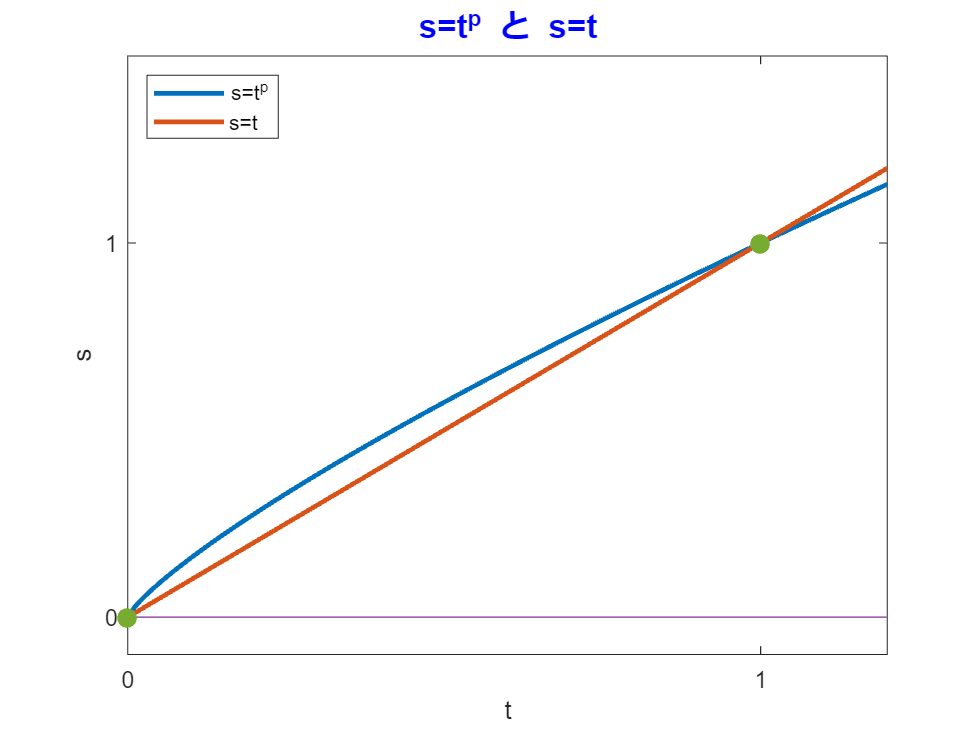

p = 0.8;
p0=zeros(1,2);
q0=zeros(1,2);
p0(1,1)=0;
p0(1,2)=1;
q0(1,1)=0;
q0(1,2)=1;
t1 = 0:0.01:1.2;
supersub=t1.^p;
linear=t1;

Z1=plot(t1,supersub,'LineWidth',2);
    ylim([-0.1 1.5])
    xlim([0 1.2])
    title('s=t^p と s=t','Color','blue','FontSize',14)
    xticks([0 1])
    xticklabels({'0','1'})
    xlabel('t')
    yticks([0 1])
    yticklabels({'0','1'})
    ylabel('s')
hold on
Z2=plot(t1,linear,'LineWidth',2);
Z3=plot(t1,zeros(121),'LineWidth',0.1);
sz1 = 70;
Z4=scatter(p0,q0,sz1,'filled');
hold off 
legend([Z1 Z2],{'s=t^p','s=t'},'Location','northwest');

## 4. 点$\bigl(a,f(a)\bigr)$を通るすべての直線を考える

$f(x)$ が $x=a$ で微分可能であるとは


$$f(x)
=
\ 
\text{[点 $\bigl(a,f(a)\bigr)$ を通る1次式]}
\ + \  
\text{[$x \rightarrow a$ のとき $x-a$ よりも速く $0$ に近づく項]}$$


の形, すなわち, **[1次式+ゴミ]** の形に分解されるということである. この1次式を


$$h(x)=f(a)+f^\prime(a)(x-a)$$
 

とおく. さらに, 点 $\bigl(a,f(a)\bigr)$を通る任意の傾き $b$ の1次式


$$g(x)=f(a)+b(x-a),
\quad
b\in\mathbb{R}$$


を考える. $h(x)$ は $g(x)$ の $b=f^\prime(a)$ となる特別な場合である. 

$x \rightarrow a$ のときの $f(x)-g(x)$ と $f(x)-h(x)$ が $0$ に近づく速さを見てみよう.  

$b \ne f^\prime(a)$ のときは $x-a$ と同程度の速さである:

$f(x)-g(x)=\bigl(f^\prime(a)-b\bigr)(x-a)+R(x)$.

$b = f^\prime(a)$ のときは $x-a$ よりも圧倒的に速い: 

$f(x)-h(x)=R(x)$.

よって $y=h(x)$ によって表される直線は曲線 $y=f(x)$ 上の点 $\bigl(a,f(a)\bigr)$ を通るすべての直線の中で唯一の特別なものであることがわかる. 直線 $y=h(x)$ を曲線 $y=f(x)$ 上の点 $\bigl(a,f(a)\bigr)$ における接線という. 

直観的には, **関数 **$f(x)$** が **$x=a$** で微分可能であるとは,  曲線 **$y=f(x)$** 上の点 **$\bigl(a,f(a)\bigr)$** を通る接線がただ一つ存在することである**, ということがわかった. 

## 5. 例 $f(x)=x^2$


$$g(x)=a^2+b(x-a), 
\quad
h(x)=a^2+2a(x-a), $$



$$f(x)-g(x)=(2a-b)(x-a)+(x-a)^2, 
\quad
f(x)-h(x)=(x-a)^2.$$


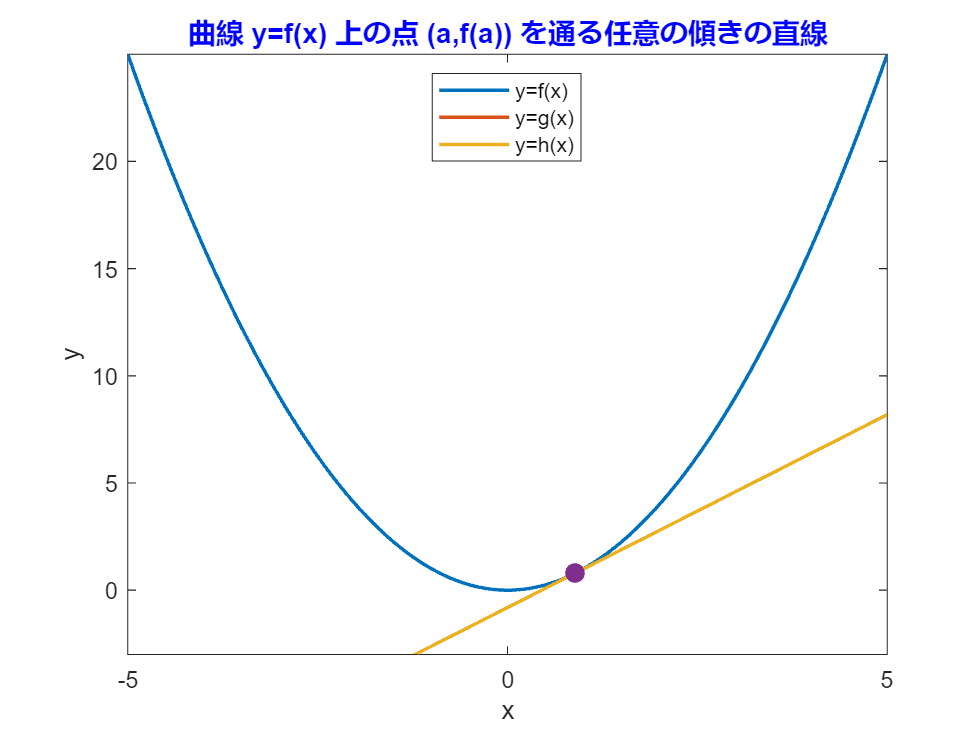

a =0.9; b = 1.8;
p1=zeros(1,1);
q1=zeros(1,1);
p1(1,1)=a;
q1(1,1)=a^2;

x1 = -5:0.01:5;
f=x1.^2;
g=a^2+b*(x1-a);
h=a^2+2*a*(x1-a);

X1=plot(x1,f,'LineWidth',1.5);
    ylim([-3 25])
    xlim([-5 5])
    title('曲線 y=f(x) 上の点 (a,f(a)) を通る任意の傾きの直線','Color','blue','FontSize',12)
    xticks([-5 0 5])
    xticklabels({'-5','0','5'})
    xlabel('x')
    yticks([0 5 10 15 20])
    yticklabels({'0','5','10','15','20'})
    ylabel('y')
%    legend('y=f(x)','y=g(x)','y=h(x)','Location','north')
hold on
X2=plot(x1,g,'LineWidth',1.5);
X3=plot(x1,h,'LineWidth',1.5);
sz2=70;
X4=scatter(p1,q1,sz2,'filled');
hold off
legend([X1 X2 X3],{'y=f(x)','y=g(x)','y=h(x)'},'Location','north')